# Find a Root with fzero

## Task 1

In this activity, you will use `fzero` to find where 0.5−sin(x)=x2 between -1 and 1.

Task

Create a function handle `rootFunction` to an anonymous function for f(x)=0.5−sin(x)−x2.

rootFunction = @(x) 0.5 - sin(x) - x.^2

rootFunction = function_handle with value:
    @(x)0.5-sin(x)-x.^2


## Task 2

Use `fplot` to plot `rootFunction` over the interval -1 to 1. Use `grid` `on` to add grid lines to the plot.

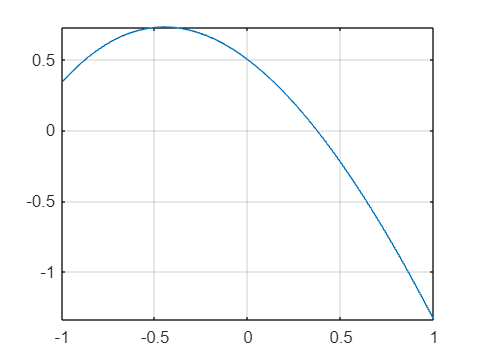

fplot(rootFunction,[-1 1])
grid on

## Task 3

Like the bisection method, if you provide an interval, `fzero` requires the interval to brackets the desired root. 

Recall that the interval must be a two element vector with values xneg and xpos where 

- xneg is a value for which f(xneg)<0, and 

- xpos is a value for which f(xpos)>0.

Task

Create a two element vector `x0` that defines an interval bracketing the root.

x0=[0.5 -0.5]

x0 =     0.5000   -0.5000


## Task 4

The syntax for calling the `fzero` function is

`x` `=` `fzero``(``fhandle``,``brackets``)`.

Task

Use `fzero` to find the root of `rootFunction` in the interval `x0`. Assign the result to the variable `x`.

x=fzero(rootFunction,x0)

x = 0.3709

## Task 5

Use `rootFunction` to evaluate (x)=0.5−sin(x)−x2 at the root you found. Assign the result to the variable `y`.

You may want to leave off the semicolon to see the result. (If x is near the root, 

f(x) should be close to 0.)

y=rootFunction(x)

y = 5.5511e-17

## Task 6

To visualize `rootFunction` and the root together, use the `hold` `on`  command to add to your current plot. 

`plot``(``xValue1``,``yValue1``)`

`hold` `on`

`plot``(``xValue2``,``yValue2``)`

`hold` `off`

 Use the `hold` `off` command when you're finished adding to your plot. 

 You can plot a point as a circle by using `"o"``,` as a third input to the `plot` function.

`plot``(``xValue``,``yValue``,``"o"``)`

Task

Add a circle to the plot marking the root's location.

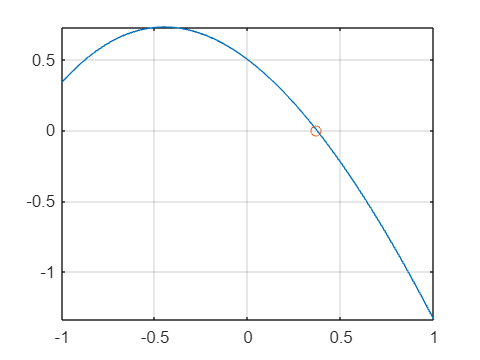

hold on
plot(x,y,"o")
hold off

## Further Practice

Notice the variable `y`. In the bisection method, you repeated the algorithm until the value of `y` was less than 0.001. Using `fzero`, the value of `y` is much closer to 0, which means `x` is a more accurate estimate for the root.